# AHP 层次分析法

# 要求获得判断矩阵 A（仅举例）

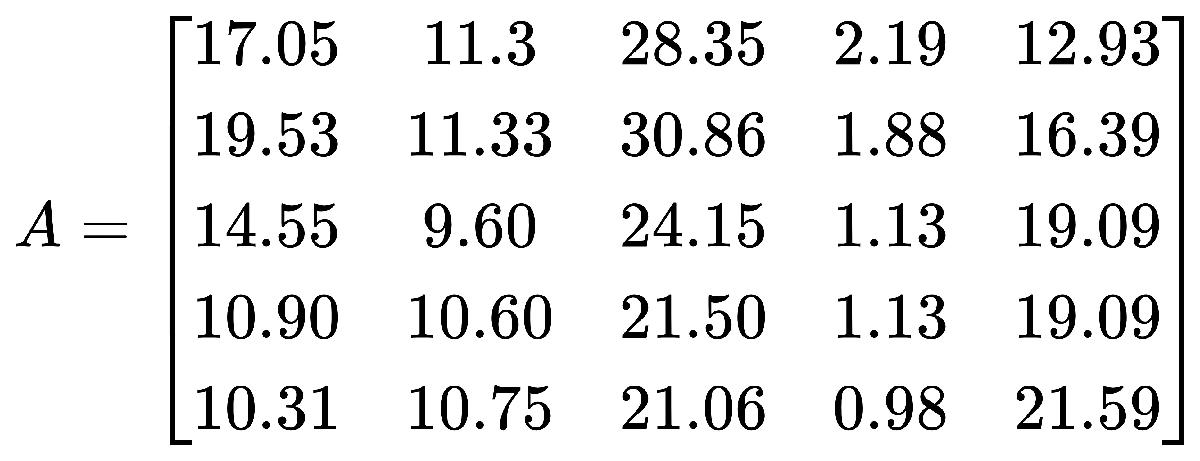

clear
clc
A = [17.0500000000000	11.3000000000000	28.3500000000000	2.19000000000000	12.9300000000000
19.5300000000000	11.3300000000000	30.8600000000000	1.88000000000000	16.3900000000000
14.5500000000000	9.60000000000000	24.1500000000000	1.87000000000000	13.8200000000000
10.9000000000000	10.6000000000000	21.5000000000000	1.13000000000000	19.0900000000000
10.3100000000000	10.7500000000000	21.0600000000000	0.980000000000000	21.5900000000000];

## 算术平均法求权重

Sum_A = sum(A);
n = size(A,1);
SUM_A = repmat(Sum_A,n,1);
% 归一化矩阵
Stand_A = A ./ SUM_A

Stand_A =     0.2357    0.2109    0.2251    0.2720    0.1543
    0.2700    0.2115    0.2451    0.2335    0.1955
    0.2011    0.1792    0.1918    0.2323    0.1649
    0.1507    0.1978    0.1707    0.1404    0.2277
    0.1425    0.2006    0.1672    0.1217    0.2576


% 矩阵行求和
sum(Stand_A,2);
disp('算术平均法求权重的结果为：');

算术平均法求权重的结果为：


disp(sum(Stand_A,2) / n)

    0.2196
    0.2311
    0.1939
    0.1775
    0.1779



## 几何平均法求权重

% prod函数和sum函数类似，一个用于乘，一个用于加  dim = 2 维度是行
Prduct_A = prod(A,2);
% 将新的向量的每个分量开n次方
Prduct_n_A = Prduct_A .^ (1/n);
% 对该列向量进行归一化即可得到权重向量
% 将这个列向量中的每一个元素除以这一个向量的和
disp('几何平均法求权重的结果为：');

几何平均法求权重的结果为：


disp(Prduct_n_A ./ sum(Prduct_n_A))

    0.2193
    0.2332
    0.1955
    0.1774
    0.1745



## 特征值法求权重

[V,D] = eig(A)

V =     0.4666    0.4143    0.4785   -0.5774    0.5596
    0.5183    0.2964   -0.6518   -0.5774    0.4427
    0.4146    0.1143   -0.2044    0.5774   -0.5693
    0.4090   -0.4745    0.4874   -0.0000    0.4054
    0.4178   -0.7087    0.2585   -0.0000    0.0490


D =    68.2950         0         0         0         0
         0    8.3274         0         0         0
         0         0   -1.2363         0         0
         0         0         0   -0.0000         0
         0         0         0         0   -0.1361


Max_eig = max(max(D));
D == Max_eig;
[r,c] = find(D == Max_eig , 1);
% 找到D中第一个与最大特征值相等的元素的位置，记录它的行和列
% 对求出的特征向量进行归一化即可得到我们的权重
V(:,c);
disp('特征值法求权重的结果为：');

特征值法求权重的结果为：


disp( V(:,c) ./ sum(V(:,c)) )

    0.2096
    0.2328
    0.1862
    0.1837
    0.1877



% 根据找到的最大特征值的列数c找到对应的特征向量，再进行标准化